# Exponential and Logistic Growth Model Fitting for Novel-2019 Coronavirus cases in China

**George Watkins, 2020-02-10**

## Data preparation

Data Source:[1]

cases = read_china_cases("china_cases.csv");
cases_dates = flip(table2array(cases(:,1)));
cases_count = flip(table2array(cases(:,2)));
data_point_number = length(cases_dates);

% Use days from first datapint as a numeric x axis, as days are the highest
% resolution available in the data
days_from_first_datapoint = days(cases_dates - repelem(min(cases_dates),data_point_number)');

## Exponential Growth

Fitted using a custom function

[a, b] = exponential_fit(days_from_first_datapoint, cases_count)

a = 1.5438e+03

b = 0.2196

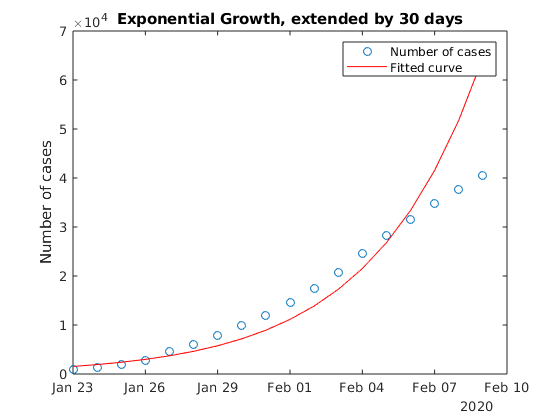


fitted_exponential_x = linspace(min(days_from_first_datapoint),max(days_from_first_datapoint),data_point_number);
fitted_exponential_y = a*exp(b*fitted_exponential_x);
plot(cases_dates,cases_count,'o',...
    cases_dates,fitted_exponential_y,'red')
legend('Number of cases','Fitted curve');
title("Exponential Growth, extended by "+extra_days +" days")
ylabel('Number of cases')

Doesn't seem to fit the data too well

## Logistic Growth

Fitted using a helper library [2]

 addpath fit_logistic
[ Qpre, p] = fit_logistic(days_from_first_datapoint,cases_count);

The resut of this library uses slightly differnt notation from our textbook. The variable p contains the data for the coefficients of the expression for the number of cases $Q$, as documented in [2]:


$$Q\left(t\right)=\frac{Q_{\inf } }{\left(1+\exp \left(-\alpha \left(t-t_{\textrm{half}} \right)\right)\right)}$$


$Q_{\inf }$ represents the case for $t\to \infty$

thalf = p(1), Qinf = p(2), alpha = p(3)

thalf = 12.1724

Qinf = 5.0361e+04

alpha = 0.2866

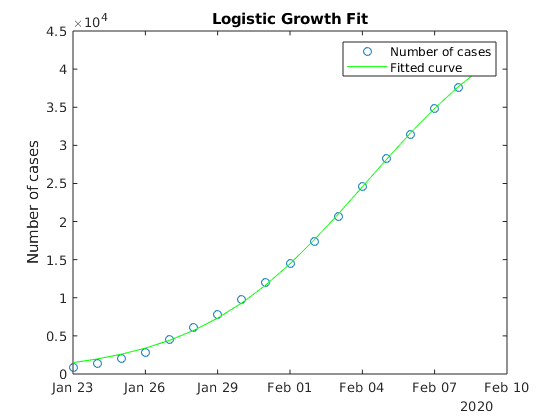

% As a formula:
logistic_fit_formula = @(t) Qinf./(1 + exp(-alpha*(t-thalf)));

% Plot
plot(cases_dates,cases_count,'o',...
    cases_dates,Qpre,'green')
legend('Number of cases','Fitted curve');
title('Logistic Growth Fit')
ylabel('Number of cases')

This model seems to fit the data much better.

## Logistic Growth Model Prediction

Extend the time interval:

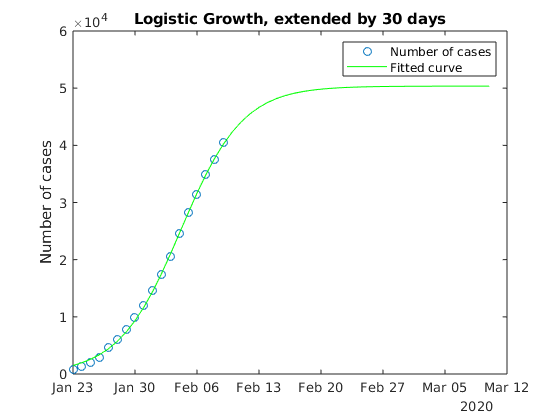

extra_days = 30;

extended_days_from_first_datapoint = [days_from_first_datapoint;max(days_from_first_datapoint)+(1:extra_days)'];
extended_cases_dates = [cases_dates;max(cases_dates)+days((1:extra_days)') ];
extended_cases_count = logistic_fit_formula(extended_days_from_first_datapoint);

plot(cases_dates,cases_count,'o',...
    extended_cases_dates,extended_cases_count,'green')
legend('Number of cases','Fitted curve');
title("Logistic Growth, extended by "+extra_days +" days")
ylabel('Number of cases')

Fits the data better, but common sense might give us a different intuition for the future development of cases of the virus.

## References

[1] Data source: [https://www.worldometers.info/coronavirus/coronavirus-cases/](https://www.worldometers.info/coronavirus/coronavirus-cases/)

[2] [James Conder (2020). fit_logistic(t,Q) (https://www.mathworks.com/matlabcentral/fileexchange/41781-fit_logistic-t-q), MATLAB Central File Exchange. Retrieved February 8, 2020.](https://www.mathworks.com/matlabcentral/fileexchange/41781-fit_logistic-t-q)